# HW 2 - Matlab Exercise 2

Module 2 consists of 8 sections. loading data as we did before is where we begin

data = load('../HMP_Dataset/Climb_sigtairs/Accelerometer-2011-03-24-10-24-39-climb_sigtairs-f1.txt')
% loading in the data from the csv matrix
data = convert(data)
x = data(:,1);
y = data(:,2);
z = data(:,3);

## Combining of signal

can be done with an anon function

S = @(a, b, c) (sqrt(a.^2 + b.^2 + c.^2 ))

with this we can convert the signal for computing the energy of it.


$$E=\int_{-\infty }^{\infty } |S|^2 \mathrm{dt}$$


We are in a discrete environment, so we need the following.


$$E=\sum_{-\infty }^{\infty } |S|^2$$


matlabs sum function can do this across the vector and we can pass in the squared magnitude

E = sum(mag_sigquared)

## 2 combine and calculate energy

sig_sig = S(x, y, z)'
mag_sigquared = abs(sig_sig).^2 
energy_sig = sum(mag_sigquared,"all","omitmissing","double")

The energy of S is obtained.

## 3 Implementation of moving average

showing the moving average working on the data below

avg_vec = [1 1 1]./3
conv_sig = conv(x,avg_vec)
plot(1:1:length(x),x,'b',1:1:length(conv_sig),conv_sig,'r')
title('combined signal and moving avg')
xlabel('samples n')
ylabel('value')
grid on
legend('original','avg')

## Here is the convolved impulse across the signals

hx = filter(avg_vec,1,x);
hy = filter(avg_vec,1,y);
hz = filter(avg_vec,1,z);
convX = conv(hx,x);
convY = conv(hy,y);
convZ = conv(hz,z);
reg_range = (1:1:length(hx))';
new_range = -floor(length(convX)/2):1:floor(length(convX)/2);
figure()
plot(new_range,convX,new_range,-convY,new_range,convZ)
grid on
figure()
plot(reg_range,hx,'k*',1:1:length(x),x,'b:',1:1:length(conv_sig),conv_sig,'r')
title('Original signal with average and filter function')
legend("h_x","x","My_{avg}")
grid on


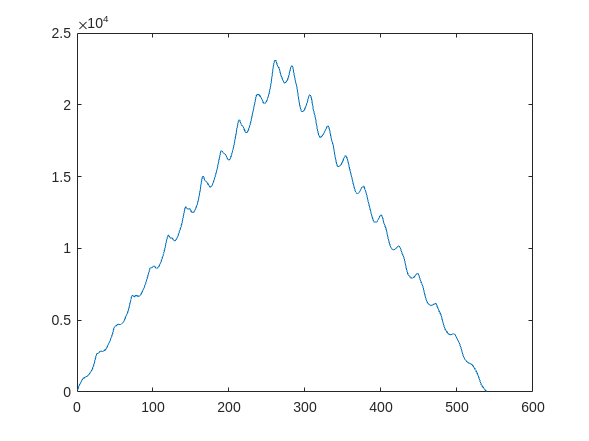

figure
test = conv(x,x);
plot(1:1:length(test),test)

function a = convert(data)
g = 9.8; % as in m/s^2
a = -1.5*g + 3*g*(data/63);
end